# **Introduction to Arduino programming using MATLAB/Simulink**

This document describes the user the first steps to follow when using the Arduino control board with a Simulink model. Previously, MATLAB and Simulink support packages for Arduino will be introduced and how to configure Simulink to interact with Arduino will be described (in this case an Arduino Due will be used). Finally, several exercises will be done regarding the analog and digital inputs and outputs.

**OBJECTIVE: Learn to use the specific blocks of analog and digital input. and output of Arduino in Simulink.**

% If you want to open the Simulink model to do experiments = true
% If you do not want to open the Simulink model = false
OpenModel = false;

# Support packages

Thanks to MATLAB / Simulink support packages for Arduino hardware, we can communicate and interact with an Arduino board. These packages allow the acquisition of analog and digital sensor data from the Arduino board and control other devices with analog and digital outputs or PWM modulation, creating a versatile and low cost platform.

Its installation is very simple, for it, follow the following steps:

- In the tab "Home" > "Adds-Ons" > "Get Adds-Ons"

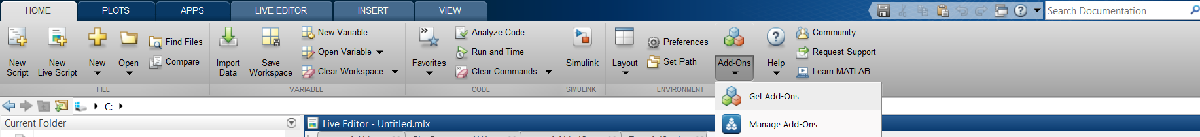

- Find the mentioned packages and click on the install button.

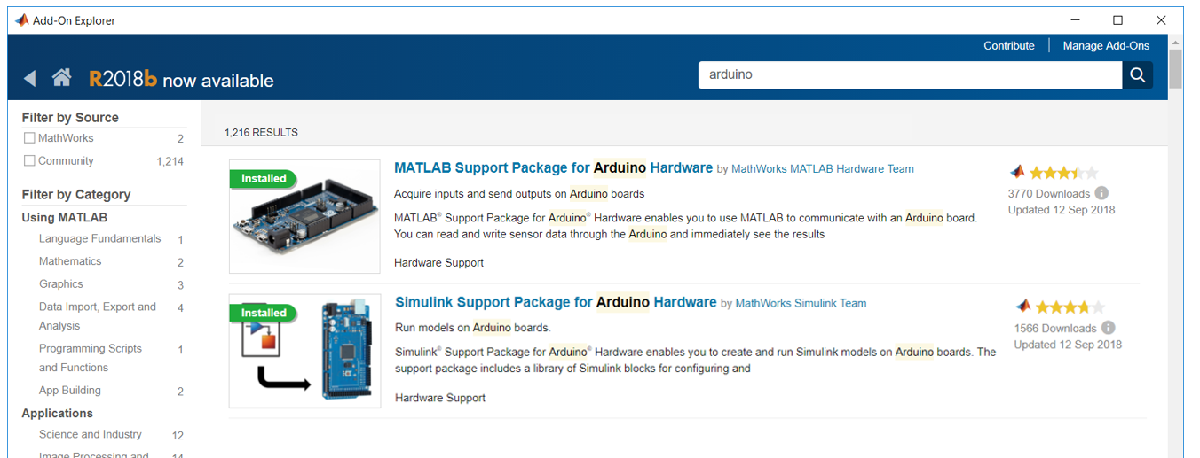

For more information:

***MATLAB support for Arduino***

Web page: [https://es.mathworks.com/hardware-support/arduino-matlab.html](https://es.mathworks.com/hardware-support/arduino-matlab.html) 

Documentaton: [http://www.mathworks.com/help/supportpkg/arduinoio/](http://www.mathworks.com/help/supportpkg/arduinoio/)

Examples: [https://es.mathworks.com/help/supportpkg/arduinoio/examples.html](https://es.mathworks.com/help/supportpkg/arduinoio/examples.html) 

***Simulink support for Arduino***

Web page: [https://es.mathworks.com/hardware-support/arduino-simulink.html](https://es.mathworks.com/hardware-support/arduino-simulink.html) 

Documentation: [http://www.mathworks.com/help/supportpkg/arduino/](http://www.mathworks.com/help/supportpkg/arduino/)

Examples: [https://es.mathworks.com/help/supportpkg/arduino/examples.html](https://es.mathworks.com/help/supportpkg/arduino/examples.html) 

# MATLAB configuration

To connect to an official Arduino board.

a = arduino()

If you are using an unofficial Arduino hardware (clone), spcify the port and the name of the board to establish the connection.

a = arduino('COM3','Uno')

The MATLAB support package for Arduino provides a list of functions that allow the access to digital and analog inputs and outputs: 

- configurePin: establishes the directionality (input or output) of a digital pin. 

- writeDigitalPin - writes to a digital output. 

- readDigitalPin - reads a digital input. 

- writePWMDutyCycle: writes to a PWM output, duty cycle in 0-1. 

- writePWMVoltage: writes to a PWM output, duty cycle in 0-5 (effective volts). 

- readVoltage - reads an analog input.

You can find a detailed description of each function in MATLAB using its help or through the documentation provided in the previous section.

# Simulink configuration

When configuring Simulink to interact with Arduino we have to take into account three steps. The first would be to choose the device to use; the second, the mode we want to use it and the last one, the execution time..

***Choosing the device ***

To specify the hardware configurations, in Simulink we will select **Simulation > Model Configuration Parameters**, or we will click on the button “*Model Configuration Parameters button*”   , which is in the Simulink toolbar, as it can be seen on the following image.

Once inside, we will select the  **Hardware Implementation **tab and in the **Hardware Board** option we will select the hardware we are using, in this case, as mentioned above, an Arduino Due will be used.

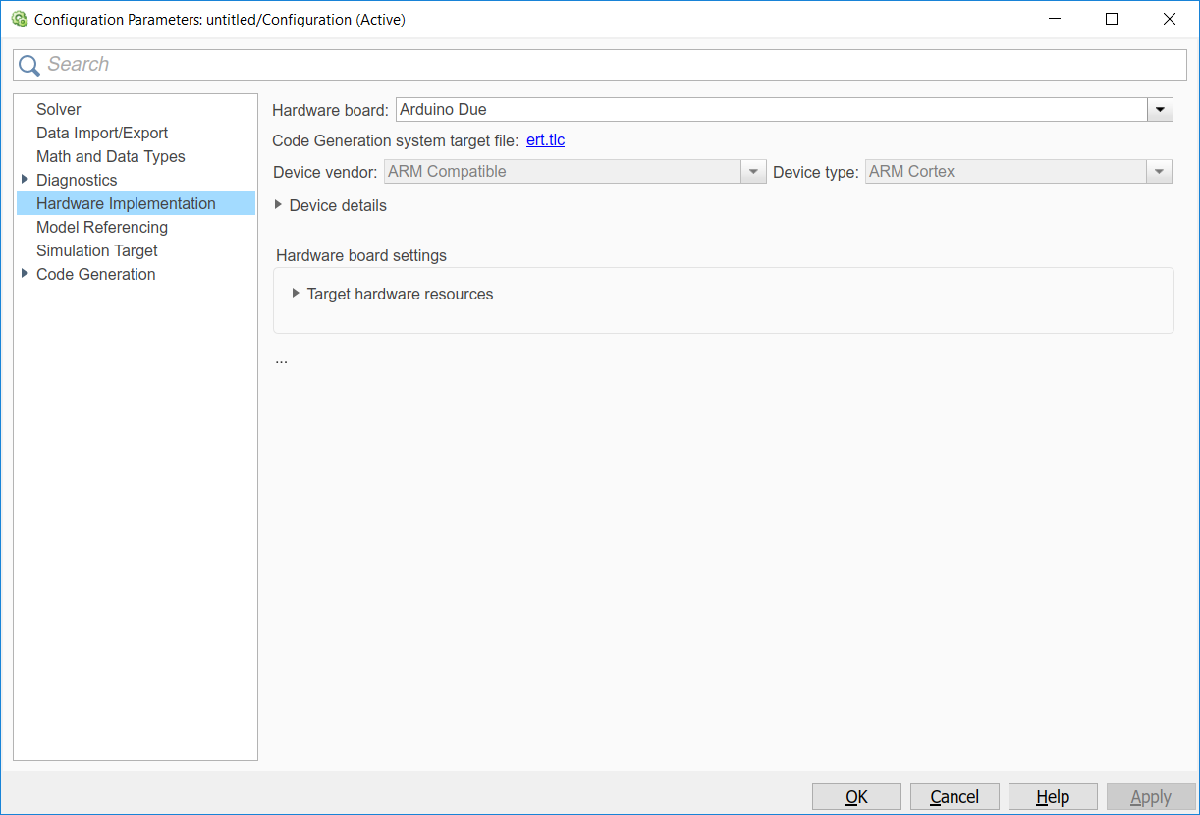

***Simulation mode***

Since the hardware to be used is an external hardware, the mode in which the Simulink model is executed must be "**external**". Thanks to this mode, we connect the block diagram created in Simulink with our application, which executes the model in the target hardware.

In addition to this, it also gives us the option to compile the code and transfer it to our microcontroller, so the model will not have to be connected to Simulink. To do this, use the "**Deploy to Hardware**" button.

***Execution time***

The third concept to take into account is the execution time, thanks to this option, we can choose the time that you want the model to be running. If you want to execute it until a certain interruption, it will be delimited by typing "**Inf**".

Keeping in mind these three steps, we can now interact with the Arduino using Simulink. That is why in the next section several exercises will be carried out with which we will learn the basics to be able to deal with it.

# Exercises

In this section several exercises are carried out with which the concepts of digital and analog inputs and outputs of Arduino will be more easily internalized using Simulink.

***Exercise 1******: Digital output***

This first exercise tries to turn on the integrated LED of the microcontroller. This led is incorporated in almost all Arduino boards and its enumeration varies with the board in use. In the case of the Arduino Due, this LED is connected to pin 13, that is why the following block diagram has been made.

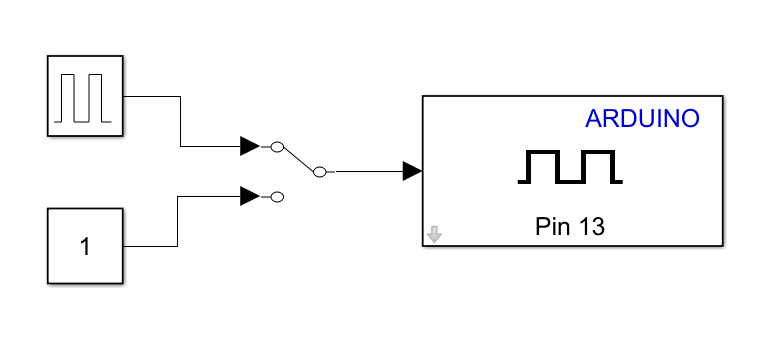

Thanks to this block diagram we can analyze how to turn on a led by 0 and 1 or by a pulse signal by thanks to the manual switch.

In order to know to which pin your Arduino board's built-in led is connected to: [https://www.arduino.cc/en/Tutorial/Blink](https://www.arduino.cc/en/Tutorial/Blink) 

if OpenModel
    cd('..')
    FolderName = [pwd filesep 'Common' filesep 'P0'];
    addpath([pwd filesep 'Common' filesep 'P0']);
    open DigitalOut.slx
end

***Exercise 2:****** Digital input***

This second exercise consists of obtaining a digital signal by means of a button. When the button is pressed, a 1 Boolean will be obtained in the scope of Simulink. Therefore, when the button is not activated, what we will obtain will be a 0. To do this, the following block diagram has been created.

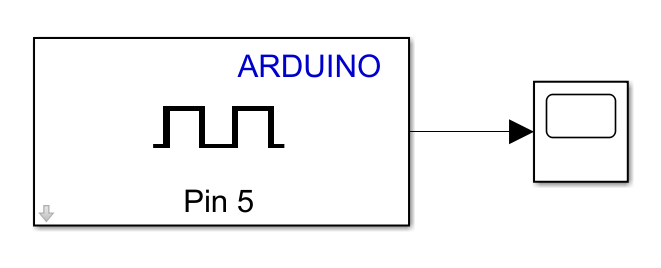

Together with the next circuit:

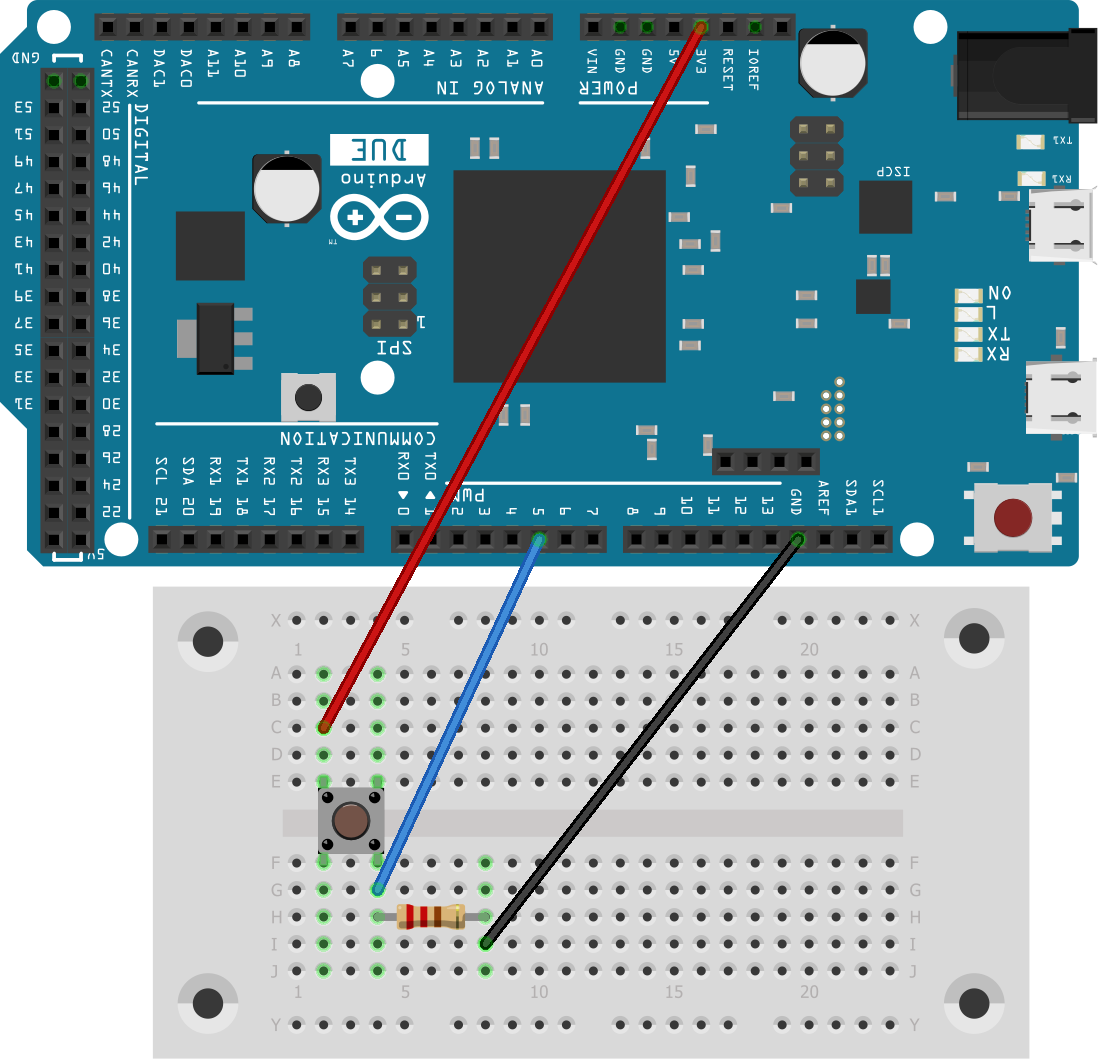

if OpenModel
    FolderName = [pwd filesep 'Common' filesep 'P0'];
    addpath([pwd filesep 'Common' filesep 'P0']);
    open DigitalIn.slx
end

***Exercise 3:****** Analog output***

In this exercise, we want to turn on a led by analog signal. For this, we will use the DAC pin of the Arduino Due. These pins are responsible for converting a digital signal into analog. We want to turn on and off a led progressively and at different frequencies, that is why the following block diagram has been designed.

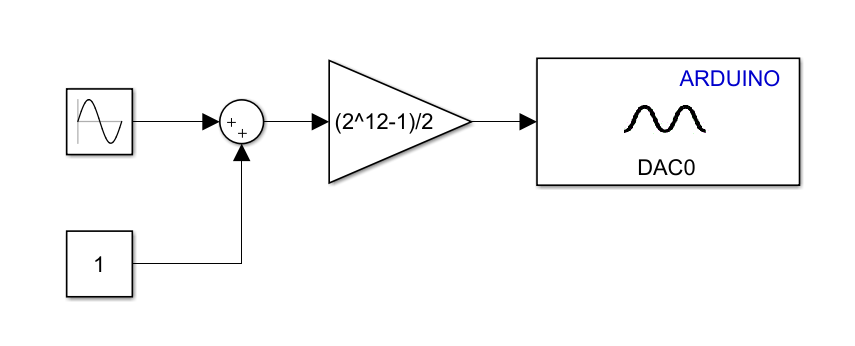 

A sinusoidal signal centered on 0.5 and an amplitude of 0.5 is applied. With which the led will blink at the frequency of the sinewave signal. To do this, the following circuit has been created:

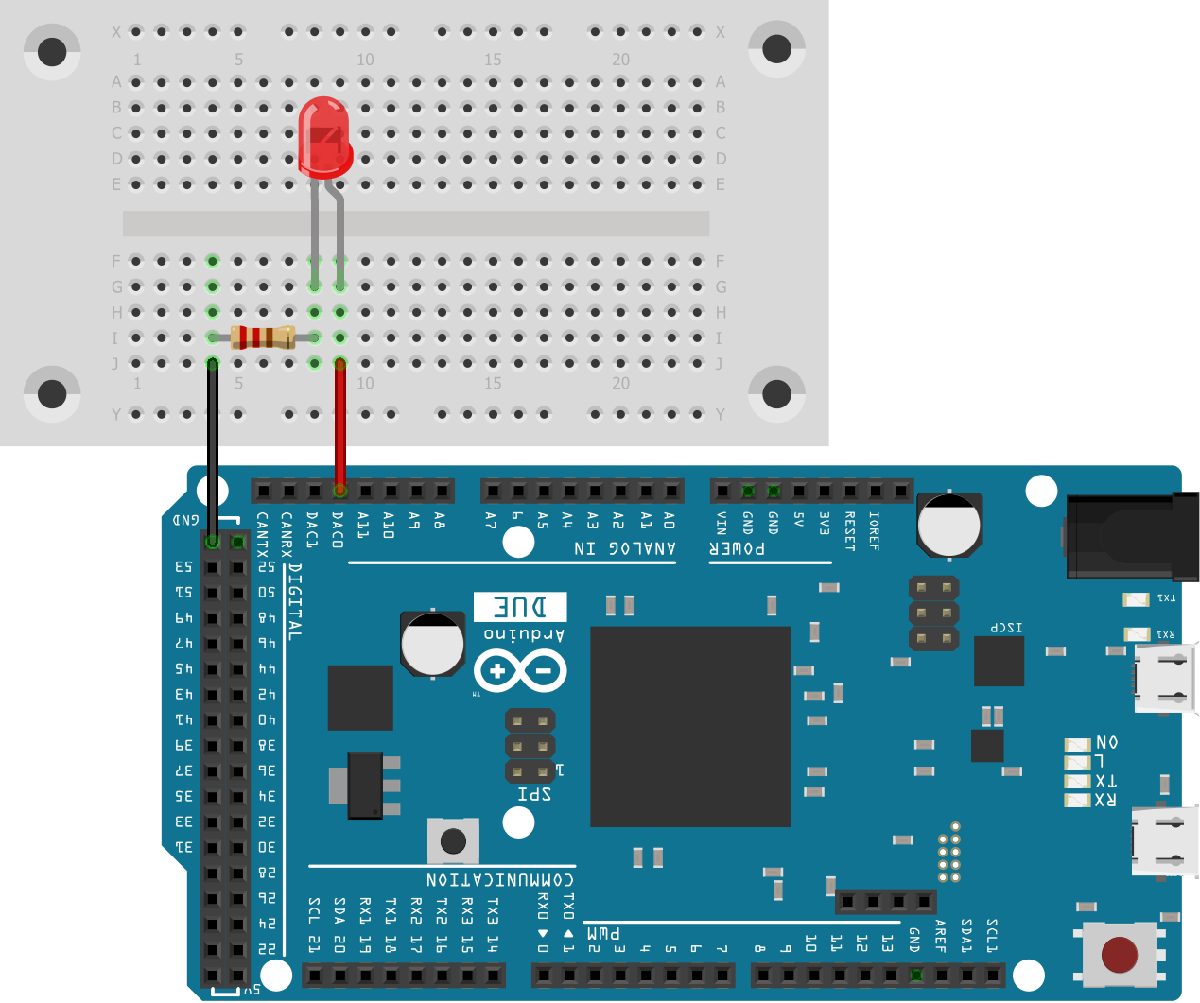

if OpenModel
    FolderName = [pwd filesep 'Common' filesep 'P0'];
    addpath([pwd filesep 'Common' filesep 'P0']);
    open AnalogOut.slx
end

***Exercise 4:****** Analog input***

Finally, it is desired to obtain an analog signal. For this, a potentiometer has been used and the following block diagram has been designed.

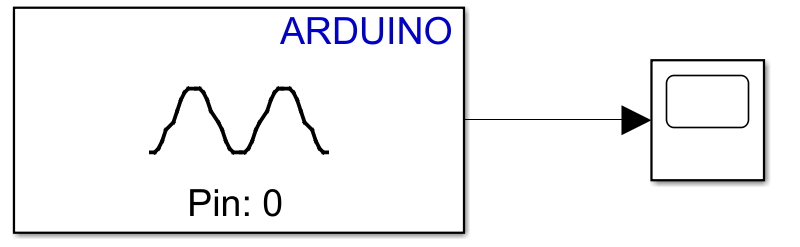

In this case, the circuit created is the following:

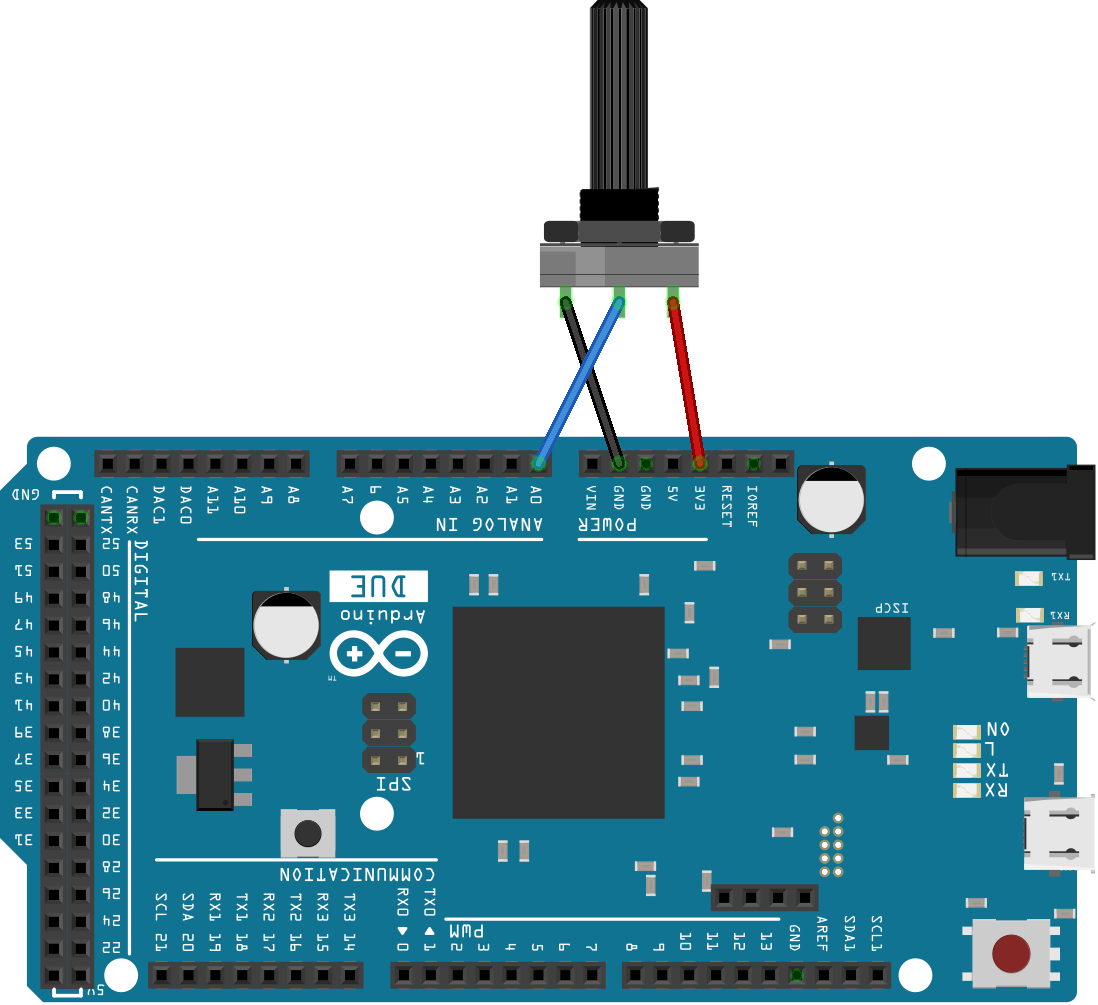

if OpenModel
    FolderName = [pwd filesep 'Common' filesep 'P0'];
    addpath([pwd filesep 'Common' filesep 'P0']);
    open AnalogIn.slx
end

***Conclusion:***

Once understanding these four concepts, block diagrams can be created where all of the aforementioned concepts are mixed together and thus create a control system. For more examples of Arduino in MATLAB or Simulink:

MATLAB & Arduino examples: [https://es.mathworks.com/help/supportpkg/arduinoio/examples.html](https://es.mathworks.com/help/supportpkg/arduinoio/examples.html) 

Simulink & Arduino examples: [https://es.mathworks.com/help/supportpkg/arduino/examples.html](https://es.mathworks.com/help/supportpkg/arduino/examples.html) 